# Convolutional dictionary learning with NSOLT

Example of grayscale image processing

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2020a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2020, Shogo MURAMATSU, All rights reserved.

## Preparation

clear 
close all
support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## Parameter settings

- Decimation factor

- Number of channels

- Sparsity ratio

- Number of iterations

- Standard deviation of initial angles

- Patch size for training

- Number of patches

% Decimation factor (Strides)
decFactors = [2 2]; % [My Mx]
nDecs = prod(decFactors);

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [3 3]; % [Ps Pa] (Ps=Pa)
redundancyRatio = sum(nChannels)/nDecs

redundancyRatio = 1.5000

% Sparsity ratio
sparsityRatio = 1/2;

% Number of iterations
nIters = 5;

% Standard deviation of initial angles
stdInitAng = pi/6;

% Patch size for training
szPatchTrn = [16 16]; % > [ (Ny+1)My (Nx+1)Mx ]

% Number of patchs per image
nSubImgs = 64;

% No DC-leakage
noDcLeakage = true;

Setting of dictionary update step

opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    ...'InitialLearnRate',0.0100,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,...
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',10,...20,...
    'MiniBatchSize',16,...64,...
    ...'Verbose',1,...
    ...'VerboseFrequency',50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','none',...'training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Convolutional dictionary learning

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{s}_n\|_0\leq K,$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a convolutional dictionary with the design parameter vector $\mathbf{\theta}}$.

#### Algorithm:

Iterate the sparse approximation step and the dictionary update step.

- Sparse approximation step

                
$$\hat{\mathbf{s}}_n=\arg\min_{\mathbf{s}_n}\frac{1}{2} \|\mathbf{v}_n-\hat{\mathbf{D}}\mathbf{s}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{s}_n\|_0\leq K$$


- Dictionary update step

                
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2$$


                
$$\hat{\mathbf{D}}=\mathbf{D}_{\hat{\mathbf{\theta}}$$


## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【Example】For $P/2=3$, a parametric orthonormal matrix $\mathbf{U}(\mathbf{\theta},\mathbf{\mu})$ can be constructed by 

        
$$\mathbf{U}(\mathbf{\theta},\mathbf{\mu}) \colon = \left(\begin{array}{cc} \mu_1 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right)
%
\left(\begin{array}{ccc} 
 1 & 0 & 0 \\
0 & \cos\theta_2& -\sin\theta_2 \\ 
0 & \sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & -\sin\theta_1  \\ 
 0 & 1 & 0 \\
\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_0& -\sin\theta_0 & 0 \\ 
\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right),$$


        
$${\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & \sin\theta_1  \\ 
 0 & 1 & 0 \\
-\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right),$$


where $\mathbf{\theta}\in\mathbb{R}^{(P-2)P/8}$ and $\mathbf{\mu}=\{-1,1\}^{P/2}$. For the sake of simplification, the sign parameters $\mu_k$ are fixed to $-1$for $\mathbf{U}_n^{\{d\}}$ witn odd $n$, otherwise they are fixed to $+1$.

Partial differentiation can be, for examle, conducted as

        
$$\frac{\partial}{\partial \theta_1}{\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
-\sin\theta_1& 0 & \cos\theta_1  \\ 
 0 & 0 & 0 \\
-\cos\theta_1 & 0 &  -\sin\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right).$$


### Definition of custom layers and networks 

Use a custom layer of Deep Learning Toolbox to implement Synthesis NSOLT (Synthesis NSOLT).

#### Definition of layers w/ Learnable properties

- Final rotation: $\mathbf{V}_0^T$ (saivdr.dcnn.nsoltFinalRotationLayer)

- Intermediate rotation: ${\mathbf{V}_n^{\{d\}}}^T$ (saivdr.dcnn.nsoltIntermediateRotationLayer)

#### Definition of layers w/o Learnable properties

- Bivariate inverese DCT (2-D IDCT): $\mathbf{E}_0^T=\mathbf{E}_0^{-1}$ (saivdr.dcnn.nsoltBlockDctLayer)

- Vertical up extension: $\mathbf{Q}^T(z_\mathrm{v}^{-1})$ (saivdr.dcnn.nsoltAtomExtensionLayer)

- Vertical down extension: $\bar{\mathbf{Q}}^T(z_\mathrm{v}^{-1})$  (saivdr.dcnn.nsoltAtomExtensionLayer)

- Horizontal left extension: $\mathbf{Q}^T(z_\mathrm{h}^{-1})$ (saivdr.dcnn.nsoltAtomExtensionLayer)

- Horizontal right extension: $\bar{\mathbf{Q}}^T(z_\mathrm{h}^{-1})$ (saivdr.dcnn.nsoltAtomExtensionLayer)

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

% Construction of layers
import saivdr.dcnn.*
analysisNsoltLayers = [
    imageInputLayer(szPatchTrn,...
        'Name','input','Normalization','none')
        
    nsoltBlockDct2dLayer('Name','E0',...
        'DecimationFactor',decFactors)
    nsoltInitialRotation2dLayer('Name','V0',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)
        
    nsoltAtomExtension2dLayer('Name','Qh1rl',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh1',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh2lu',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')
    %%{
    nsoltAtomExtension2dLayer('Name','Qh3rl',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vh3',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh4lu',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh4',...
        'NumberOfChannels',nChannels,'Mode','Analysis')        
    %%}
    nsoltAtomExtension2dLayer('Name','Qv1dl',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv1',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv2uu',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv2',...
        'NumberOfChannels',nChannels,'Mode','Analysis')
    %%{
    nsoltAtomExtension2dLayer('Name','Qv3dl',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Lower')
    nsoltIntermediateRotation2dLayer('Name','Vv3',...
        'NumberOfChannels',nChannels,'Mode','Analysis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv4uu',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv4',...
        'NumberOfChannels',nChannels,'Mode','Analysis')        
    %%}
    ]

analysisNsoltLayers =   次の層をもつ 19x1 の Layer 配列:

     1   'input'   イメージの入力                                    16x16x1 イメージ
     2   'E0'      saivdr.dcnn.nsoltBlockDct2dLayer               Block DCT of size 2x2
     3   'V0'      saivdr.dcnn.nsoltInitialRotation2dLayer        NSOLT initial rotation (ps,pa) = (3,3), (mv,mh) = (2,2)
     4   'Qh1rl'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (3,3)
     5   'Vh1'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (3,3)
     6   'Qh2lu'   saivdr.dcnn.nsoltAtomExtension2dLayer          Left shift Upper Coefs. (ps,pa) = (3,3)
     7   'Vh2'     saivdr.dcnn.nsoltIntermediateRotation2dLayer   Analysis NSOLT intermediate rotation (ps,pa) = (3,3)
     8   'Qh3rl'   saivdr.dcnn.nsoltAtomExtension2dLayer          Right shift Lower Coefs. (ps,pa) = (3,3)
     9   'Vh3'     saivdr.dcnn.

synthesisNsoltLayers = [
    imageInputLayer([szPatchTrn./decFactors sum(nChannels)],...
        'Name','subband images','Normalization','none')
    %%{
    nsoltIntermediateRotation2dLayer('Name','Vv4~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv4uu~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv3~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv3dl~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')        
    %%}
    nsoltIntermediateRotation2dLayer('Name','Vv2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qv2uu~',...
        'NumberOfChannels',nChannels,'Direction','Down','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vv1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qv1dl~',...
        'NumberOfChannels',nChannels,'Direction','Up','TargetChannels','Lower')
    %%{
    nsoltIntermediateRotation2dLayer('Name','Vh4~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh4lu~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh3~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh3rl~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower')        
    %%}
    nsoltIntermediateRotation2dLayer('Name','Vh2~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis')
    nsoltAtomExtension2dLayer('Name','Qh2lu~',...
        'NumberOfChannels',nChannels,'Direction','Right','TargetChannels','Upper')
    nsoltIntermediateRotation2dLayer('Name','Vh1~',...
        'NumberOfChannels',nChannels,'Mode','Synthesis','Mus',-1)
    nsoltAtomExtension2dLayer('Name','Qh1rl~',...
        'NumberOfChannels',nChannels,'Direction','Left','TargetChannels','Lower') 
        
    nsoltFinalRotation2dLayer('Name','V0~',...
        'NumberOfChannels',nChannels,'DecimationFactor',decFactors,...
        'NoDcLeakage',noDcLeakage)        
    nsoltBlockIdct2dLayer('Name','E0~',...
        'DecimationFactor',decFactors) 
    ]

synthesisNsoltLayers =   次の層をもつ 19x1 の Layer 配列:

     1   'subband images'   イメージの入力                                    8x8x6 イメージ
     2   'Vv4~'             saivdr.dcnn.nsoltIntermediateRotation2dLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     3   'Qv4uu~'           saivdr.dcnn.nsoltAtomExtension2dLayer          Down shift Upper Coefs. (ps,pa) = (3,3)
     4   'Vv3~'             saivdr.dcnn.nsoltIntermediateRotation2dLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     5   'Qv3dl~'           saivdr.dcnn.nsoltAtomExtension2dLayer          Up shift Lower Coefs. (ps,pa) = (3,3)
     6   'Vv2~'             saivdr.dcnn.nsoltIntermediateRotation2dLayer   Synthesis NSOLT intermediate rotation (ps,pa) = (3,3)
     7   'Qv2uu~'           saivdr.dcnn.nsoltAtomExtension2dLayer          Down shift Upper Coefs. (ps,pa) = (3,3)
     8   'Vv1~'             saivdr.dcnn.nsoltIntermediateRota

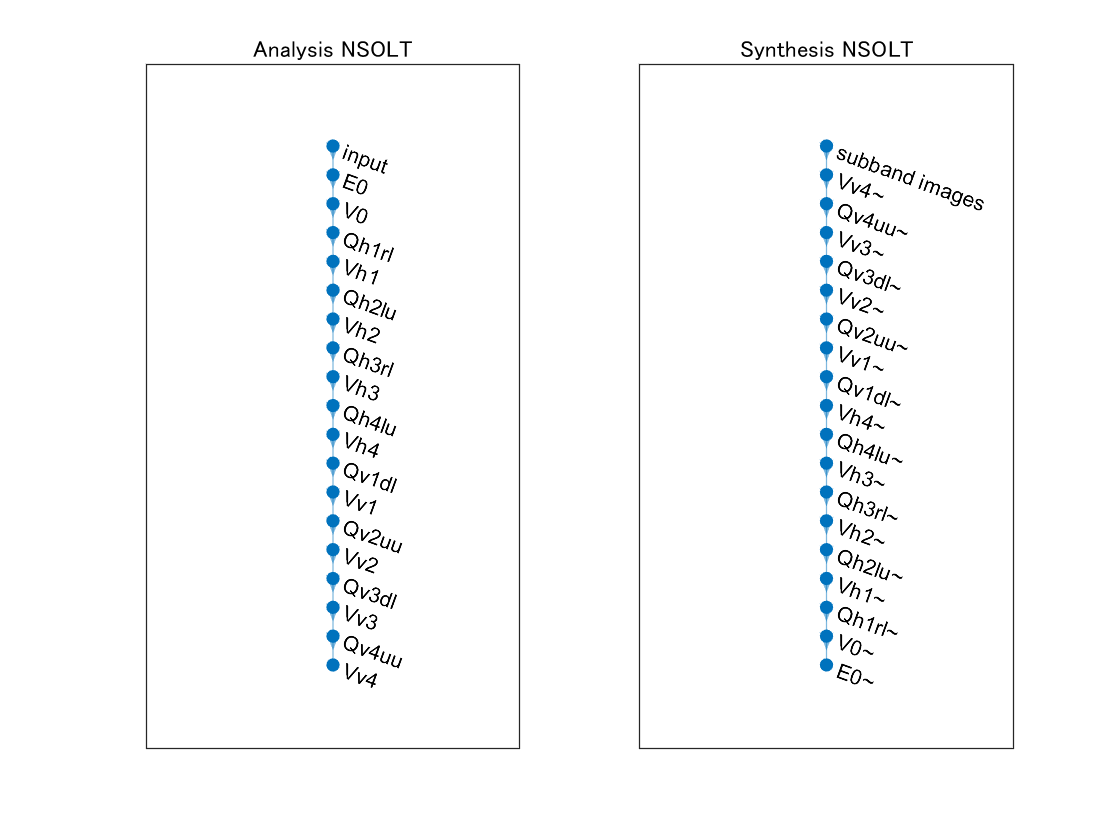

% Layer graph
analysislgraph = layerGraph(analysisNsoltLayers);
synthesislgraph = layerGraph(synthesisNsoltLayers);
figure(1)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

% Construction of deep learning network.
analysisnet = dlnetwork(analysislgraph);
synthesisnet = dlnetwork(synthesislgraph);
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    synthesisnet.Learnables.Value(iLearnable) = ...
    cellfun(@(x) x+stdInitAng*randn(), ...
    synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
end
analysisnet = copyparameters(synthesisnet,analysisnet);

### Confirmation of perfect reconstruction

x = rand(szPatchTrn,'single');
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
dls = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls);
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 2.4578e-12"



### Initial state of the atomic images

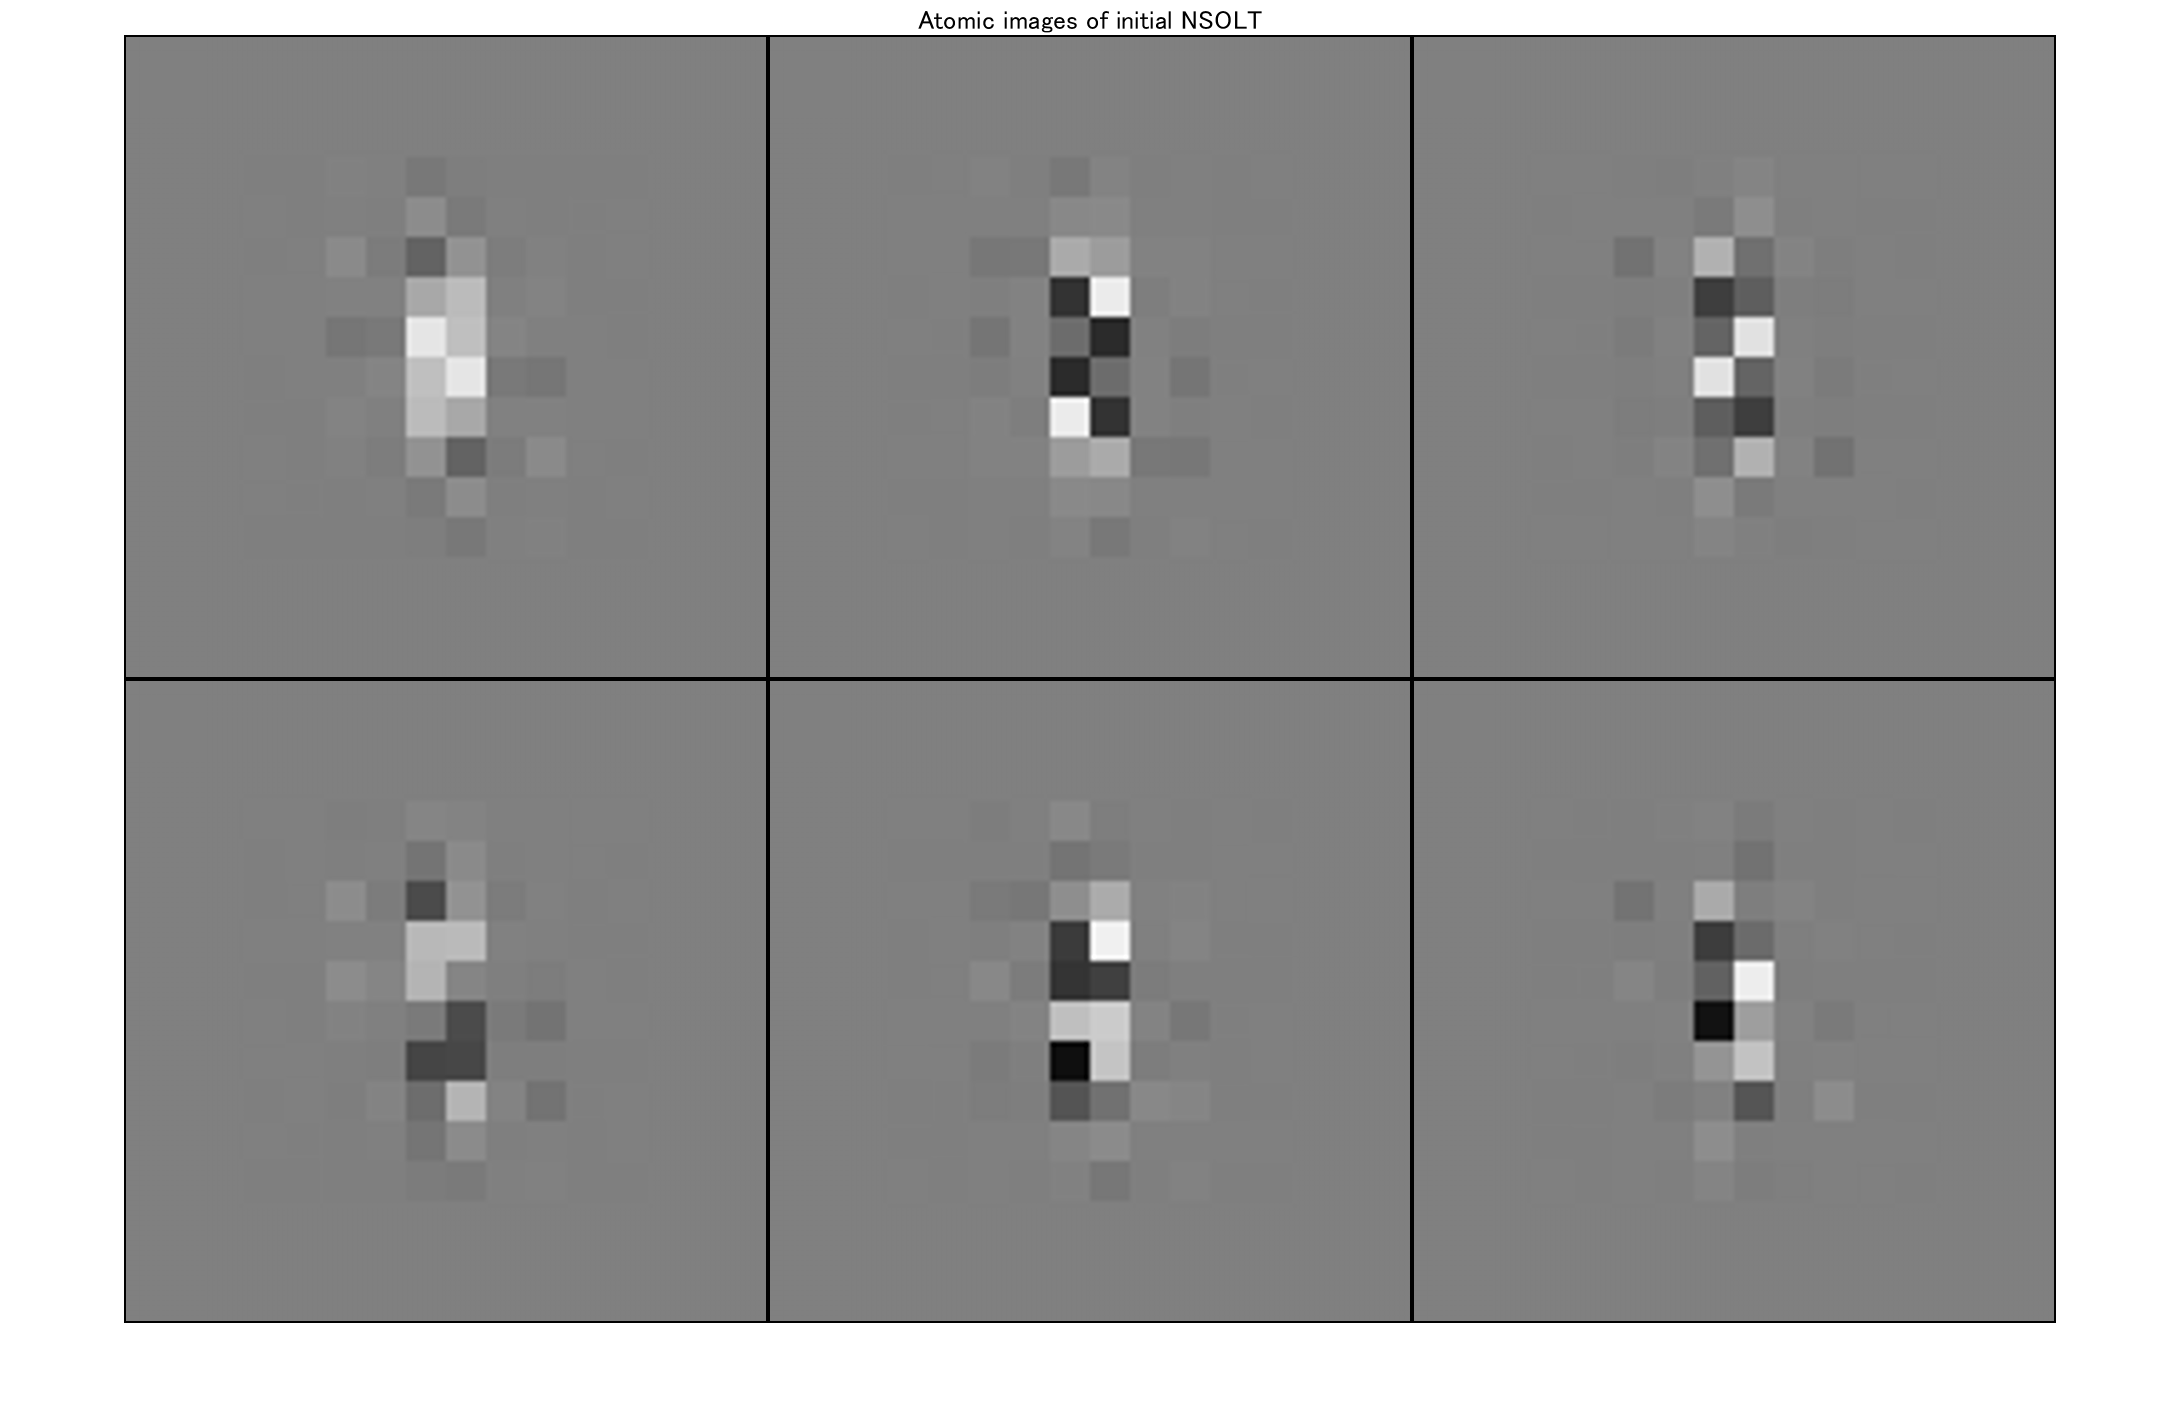

subbandImages = dlarray(zeros([szPatchTrn./decFactors sum(nChannels)],'single'),'SSC');
atomicImages = zeros([szPatchTrn 1 sum(nChannels)]);
for iAtom = 1:sum(nChannels)
    deltaImage = subbandImages;
    deltaImage(round(end/2),round(end/2),iAtom)  = 1;
    atomicImages(:,:,1,iAtom) = extractdata(synthesisnet.predict(deltaImage));
end
figure(2)
mRows = 2^(nextpow2(sqrt(sum(nChannels)))-1);
mCols = ceil(sum(nChannels)/mRows);
montage(circshift(imresize(atomicImages,8,'nearest'),[8 8 0])+.5,...
    'Size',[mRows mCols],'BorderSize',[2 2])
title('Atomic images of initial NSOLT')

### Preparation of traning image

Randomly extracting patches from the image data store

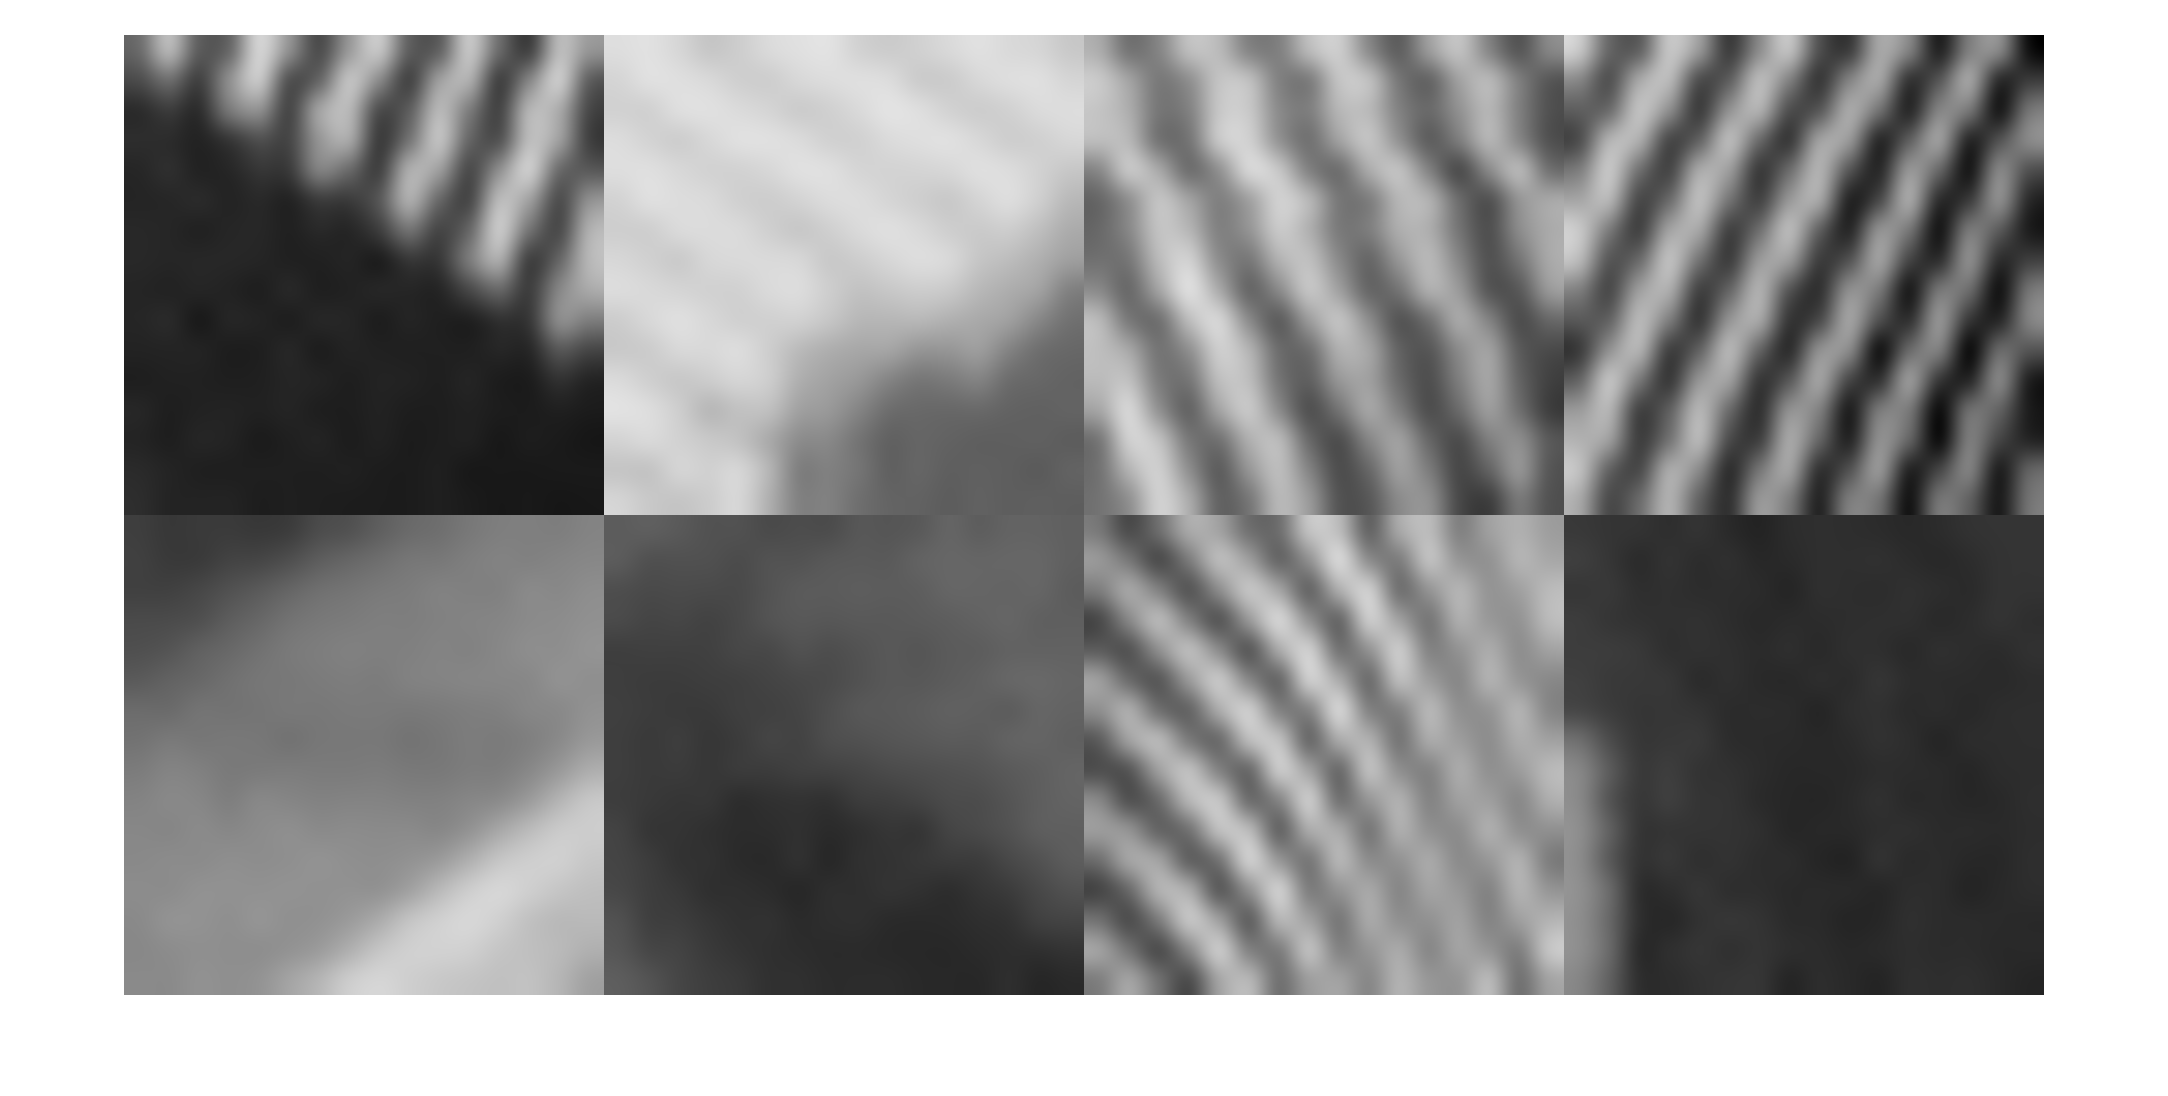

imds = imageDatastore("./data/barbara.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,...
    'PatchesPerImage',nSubImgs);
figure(3)
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

### Alternative iteration of sparse approximation step and dictioary update step

- Sparse approximation： Iterative hard thresholding

- Dictionary update： Stochastic gradient descent

Iterative calculation of alternative steps

for iIter = 1:nIters
    
    % Sparse approximation (Applied to produce an object of TransformedDatastore)
    coefimgds = transform(patchds,@(x) iht4inputimage(x,analysisnet,synthesisnet,sparsityRatio));
    
    % Synthesis dictionary update
    trainlgraph = synthesislgraph.addLayers(regressionLayer('Name','regression output'));
    trainlgraph = trainlgraph.connectLayers('E0~','regression output');
    synthesisdagnet = trainNetwork(coefimgds,trainlgraph,opts);

    % Analysis dictionary update (Copy parameters from synthesizer to
    % analyzer)
    synthesislgraph = layerGraph(synthesisdagnet); 
    synthesislgraph = removeLayers(synthesislgraph,'regression output');
    synthesisnet = dlnetwork(synthesislgraph);
    analysisnet = copyparameters(synthesisnet,analysisnet);
    
    % Check the adjoint relation (perfect reconstruction)
    x = rand(szPatchTrn,'single');
    dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
    dls = analysisnet.predict(dlx);
    dly = synthesisnet.predict(dls);
    display("MSE: " + num2str(mse(dlx,dly)))
    
end

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０１：４９　｜　　　　　　　　　１．１０　｜　　　　　　　０．６　｜　　０．０１００　｜
｜　　　　　１０　｜　　　４０　｜　　　　　００：１０：３６　｜　　　　　　　　　０．５８　｜　　　　　　　０．２　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 1.376e-12"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０１：４３　｜　　　　　　　　　０．３９　｜　　　７．４ｅ－０２　｜　　０．０１００　｜
｜　　　　　１０　｜　　　４０　｜　　　　　００：１２：００　｜　　　　　　　　　０．４２　｜　　　８．７ｅ－０２　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 1.2936e-12"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０１：５２　｜　　　　　　　　　０．２１　｜　　　２．３ｅ－０２　｜　　０．０１００　｜
｜　　　　　１０　｜　　　４０　｜　　　　　００：１４：４５　｜　　　　　　　　　０．３９　｜　　　７．５ｅ－０２　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 1.6281e-12"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０２：２８　｜　　　　　　　　　０．４０　｜　　　７．９ｅ－０２　｜　　０．０１００　｜
｜　　　　　１０　｜　　　４０　｜　　　　　００：１４：４７　｜　　　　　　　　　０．２７　｜　　　３．８ｅ－０２　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 9.5246e-13"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０２：３７　｜　　　　　　　　　０．２９　｜　　　４．２ｅ－０２　｜　　０．０１００　｜
｜　　　　　１０　｜　　　４０　｜　　　　　００：１５：０１　｜　　　　　　　　　０．３０　｜　　　４．４ｅ－０２　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 1.5956e-12"



Reshape the atoms into atomic images

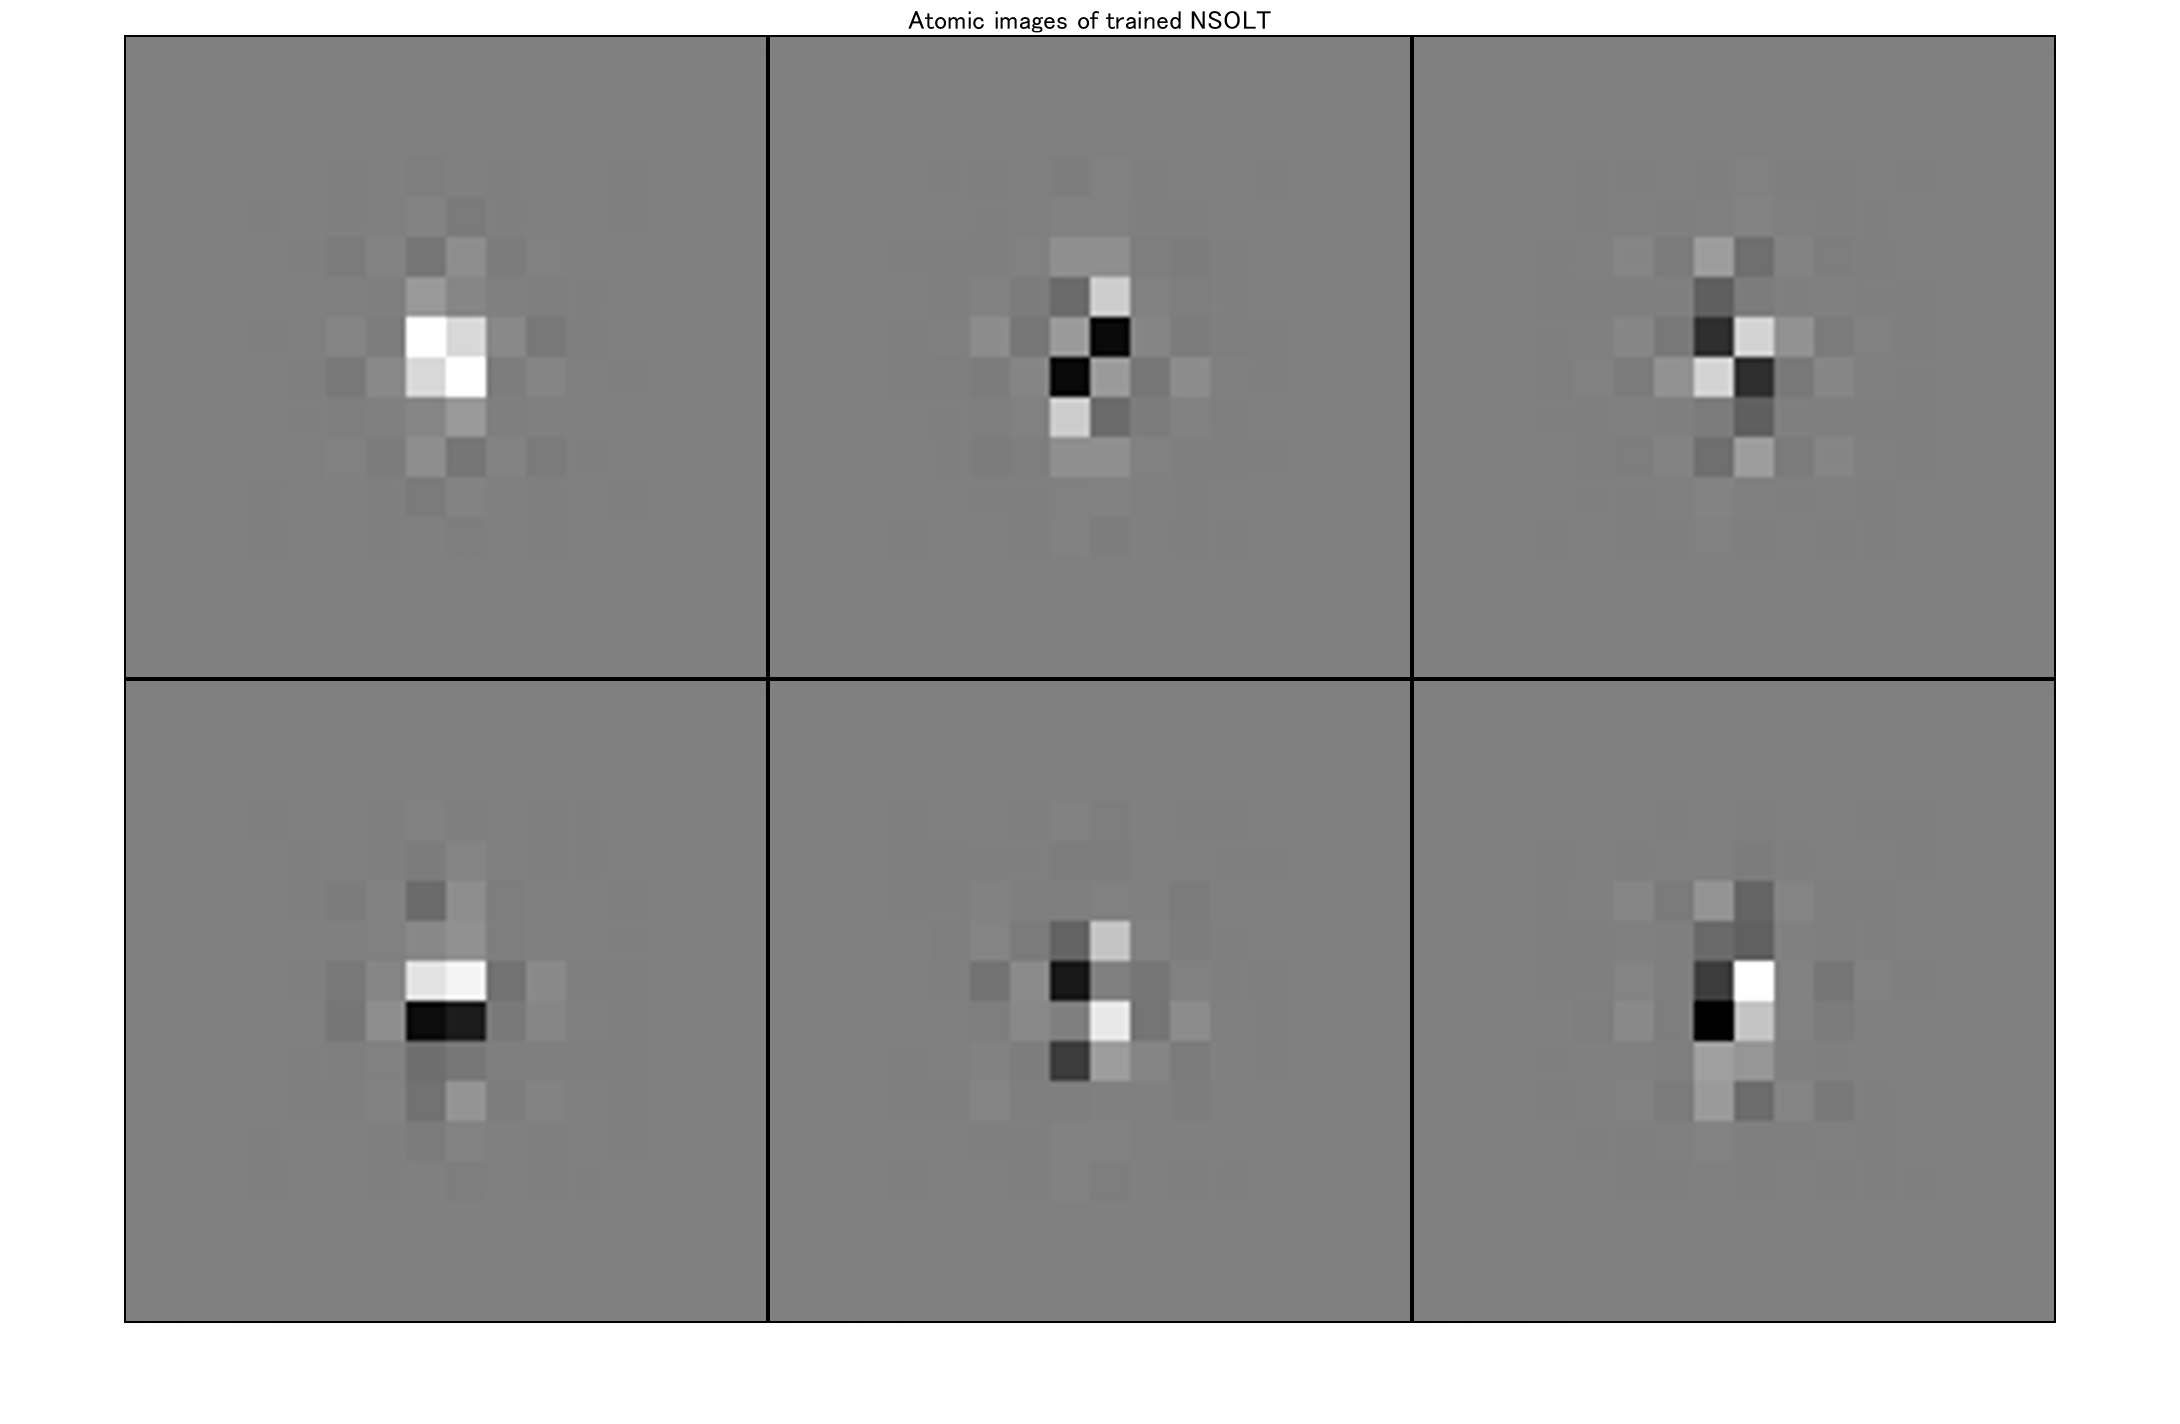

for iAtom = 1:sum(nChannels)
    deltaImage = subbandImages;
    deltaImage(round(end/2),round(end/2),iAtom)  = 1;
    atomicImages(:,:,1,iAtom) = extractdata(synthesisnet.predict(deltaImage));
end
figure(4)
montage(circshift(imresize(atomicImages,8,'nearest'),[8 8 0])+.5,...
    'Size',[mRows mCols],'BorderSize',[2 2])
title('Atomic images of trained NSOLT')

### Function of iterative hard thresholding

The input images of the patch pairs are replaced with sparse coefficients obtained by IHT, where normalization is omitted for the Parseval tight property of NSOLT.

         
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{H}_{T_K}\left(\mathbf{s}^{(t)}-\gamma \hat{\mathbf{D}}^T\left(\hat{\mathbf{D}}\mathbf{s}^{(t)}-\mathbf{v}\right)\right)$$


        
$$t\leftarrow t+1$$


where

        
$$\mathcal{H}_{T_K}(\mathbf{x})=\mathrm{sgn}(\mathbf{x})\odot\max(\mathrm{abs}(\mathbf{x}),T_K\mathbf{1})$$


【Reference】

-  T. Blumensath and M. E. Davies, "Normalized Iterative Hard Thresholding: Guaranteed Stability and Performance," in IEEE Journal of Selected Topics in Signal Processing, vol. 4, no. 2, pp. 298-309, April 2010, doi: 10.1109/JSTSP.2010.2042411.

function newds = iht4inputimage(oldds,analyzer,synthesizer,sparsityRatio)
% Loop to apply IHT process for every input patch
newds = oldds;
nImgs = length(oldds.InputImage);
for iImg = 1:nImgs
    v = dlarray(oldds.InputImage{iImg},'SSC');
    [~,coefs] = iht(v,analyzer,synthesizer,sparsityRatio);
    newds.InputImage{iImg} = coefs;
end
end

function [y,coefs] = iht(x,analyzer,synthesizer,sparsityRatio)
% Iterative hard thresholding w/o normalization
% (A Parseval tight frame is assumed)
gamma = (1.-1e-3);
nIters = 20;
nCoefs = floor(sparsityRatio*numel(x));
coefs = 0*analyzer.predict(x);
% IHT
for iter=1:nIters
    % Gradient descent
    y = synthesizer.predict(coefs);
    coefs = coefs - gamma*analyzer.predict(y-x);
    % Hard thresholding
    [~, idxsort ] = sort(abs(extractdata(coefs(:))),1,'descend');
    indexSet = idxsort(1:nCoefs);
    mask = zeros(size(coefs),'like',coefs);
    mask(indexSet) = 1;
    coefs = mask.*coefs;
    %
    %fprintf("IHT(%d) MSE: %6.4f\n",iter,mse(x,y));
end
end

### Setting up the analytical dictionary (adjoint operator)

Copying synthesis dictionary parameters to the analyisis dictionary (the adjoint operator)

function newanalysisnet = copyparameters(synthesisnet,oldanalysisnet)
newanalysisnet = oldanalysisnet;
analysisLearnables = oldanalysisnet.Learnables;
synthesisLearnables = synthesisnet.Learnables;
nLearnables = height(analysisLearnables);
for iLearnable = 1:nLearnables
    t = synthesisLearnables.Value(nLearnables-iLearnable+1);
    newanalysisnet.Learnables.Value(iLearnable) = t; 
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.